clc, clear all
syms psi q1 q2 q3 q4 q5 l1 l2 l3 l4 l5 a b c ul um un xu yu zu

## Simulacion

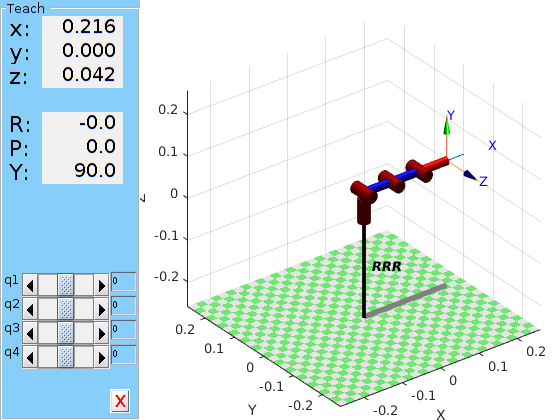

%L1 = -1; L2 = 1; L3 = 1; L4 = 1; L5 = 1;
L1 = 0.042; 
L2 = 0.072; 
L3 = 0.072;
L4 = 0.072;
L5 = 0.045;
% Primer Brazo
Lx(1) = Link([0 L1 0 pi/2]);
Lx(2) = Link([0 0 L2 0 ]);
Lx(3) = Link([0 0 L3 0 ]);
Lx(4) = Link([0 0 L4 0]);

robot = SerialLink(Lx);
robot.name = 'RRR';
robot.teach;

## Denavit-Hartembet Modelo Cinematico


H01 = D_H(q1,l1,0,pi/2);
H12 = D_H(q2,0,l2,0);
H23 = D_H(q3,0,l3,0);
H34 = D_H(q4,0,l4,0);

H05 = H01*H12*H23*H34


hx = simplify(H05(1,4))

$$hx = \cos\left(q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right)\right)$$

hy = simplify(H05(2,4))

$$hy = \sin\left(q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right)\right)$$

hz = simplify(H05(3,4))

$$hz = l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)+l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)$$



J=jacobian([hx,hy,hz],[q1,q2,q3,q4]);

J=simplify(J)

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(q_{1}\right)\,\sigma_{3} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{3} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & -l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{3} & l_{3}\,\cos\left(q_{2}+q_{3}\right)+\sigma_{4} & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)+l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)+\sigma_{4}\\ \sigma_{4}=l_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

## +UAV